%从协方差矩阵出发
clear
regions2004                                              %将保存的数据导入内存
X=zscore(data);                                          %原始数据集体标准化
[Lambda,Psi,T,Stats]=factoran(cov(X),2,'Xtype','cov');   %因子模型求解

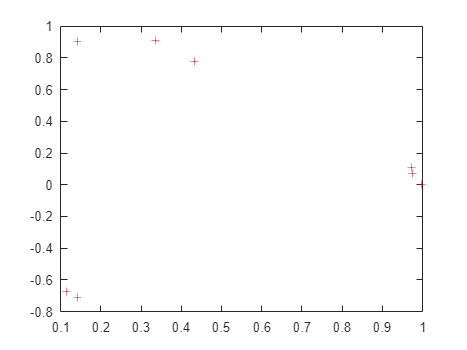

Comm=1-Psi;                                              %计算公因子方差
figure(1)
plot(Lambda(:,1),Lambda(:,2),'r+');                      %绘制载荷图

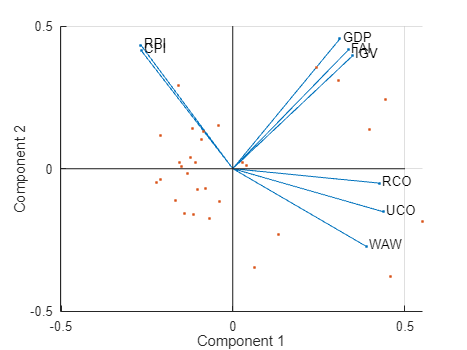


%自由度(不能为负。故本例提取的最大因子数为1)
m=8;M=2;                                                  %变量数和因子数
dfe=((m-M)^2-(m+M))/2;                                    %自由度

%二维图
figure(2)
% [coefs,score] = princomp(zscore(X));
[coefs,score] = pca(zscore(X));
biplot(coefs(:,1:2), 'scores',score(:,1:2), 'varlabels',varname);

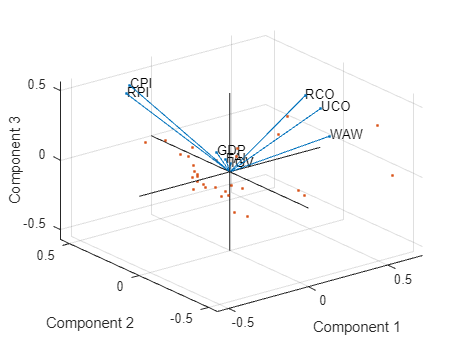


%三维图
figure(3)
% [coefs,score] = princomp(zscore(X));
[coefs,score] = pca(zscore(X));
biplot(coefs(:,1:3), 'scores',score(:,1:3), 'varlabels',varname);


%基于最大似然解的其他因子旋转方式
[Lambda, Psi, T, Stats,F]=factoran(X,2,'Score','wls','Rotate','none');      %不旋转 

[Lambda, Psi, T, stats, F] = factoran(X, 1, 'scores', 'regr');              %回归法旋转
[Lambda, Psi, T, Stats,F]=factoran(X,1,'Delta',0.001,'Display','off','MaxFunEvals',400,'MaxIter',100);%限制性旋转